clc;
clear;

load('spring_raw_data.mat');

% Trim
A_flat = A_flat(1:251,:);
A_sharp = A_sharp(1:145,:);
D_flat = D_flat(1:145,:);
D_sharp = D_sharp(1:145,:);
E_flat = E_flat(1:127,:);
E_sharp = E_sharp(1:80,:);
G_flat = G_flat(1:145,:);
G_sharp = G_sharp(1:159,:);

% Convert Time Data
A_flat(:,1) = A_flat(:,1)*.001;
A_sharp(:,1) = A_sharp(:,1)*.001;
D_flat(:,1) = D_flat(:,1)*.001;
D_sharp(:,1) = D_sharp(:,1)*.001;
E_flat(:,1) = E_flat(:,1)*.001;
E_sharp(:,1) = E_sharp(:,1)*.001;
G_flat(:,1) = G_flat(:,1)*.001;
G_sharp(:,1) = G_sharp(:,1)*.001;

% Filter out extraneous values
% A_flat(A_flat(:,2) > 500 | A_flat(:,2) < 400, :) = [];
% A_sharp(A_sharp(:,2) > 500 | A_sharp(:,2) < 400, :) = [];
% 
% D_flat(D_flat(:,2) > 350 | D_flat(:,2) < 250, :) = [];
% D_sharp(D_sharp(:,2) > 350 | D_sharp(:,2) < 250, :) = [];
% 
% E_flat(E_flat(:,2) > 664 | E_flat(:,2) < 646, :) = [];
% E_sharp(E_sharp(:,2) > 670 | E_sharp(:,2) < 656, :) = [];
% 
% G_flat(G_flat(:,2) > 200 | G_flat(:,2) < 184, :) = [];
% G_sharp(G_sharp(:,2) > 208 | G_sharp(:,2) < 194, :) = [];

% Reserve Data
A_unsmoothed = A_flat;

% Smooth
%'movmean' (default) | 'movmedian' | 'gaussian' | 'lowess' | 'loess' | 'rlowess' | 'rloess' | 'sgolay'
A_flat(:,2) = smoothdata(A_flat(:,2),'Gaussian','SamplePoints',A_flat(:,1));
A_sharp(:,2) = smoothdata(A_sharp(:,2),'Gaussian','SamplePoints',A_sharp(:,1));
D_flat(:,2) = smoothdata(D_flat(:,2),'Gaussian','SamplePoints',D_flat(:,1));
D_sharp(:,2) = smoothdata(D_sharp(:,2),'Gaussian','SamplePoints',D_sharp(:,1));
E_flat(:,2) = smoothdata(E_flat(:,2),'Gaussian','SamplePoints',E_flat(:,1));
E_sharp(:,2) = smoothdata(E_sharp(:,2),'Gaussian','SamplePoints',E_sharp(:,1));
G_flat(:,2) = smoothdata(G_flat(:,2),'Gaussian','SamplePoints',G_flat(:,1));
G_sharp(:,2) = smoothdata(G_sharp(:,2),'Gaussian','SamplePoints',G_sharp(:,1));

[ha, pos] = tight_subplot(3,2,[.01 .03],[.1 .01],[.01 .01])

ha =   6×1 Axes array:

  Axes
  Axes
  Axes
  Axes
  Axes
  Axes


pos = 6×1 cell array
    [1×4 double]
    [1×4 double]
    [1×4 double]
    [1×4 double]
    [1×4 double]
    [1×4 double]


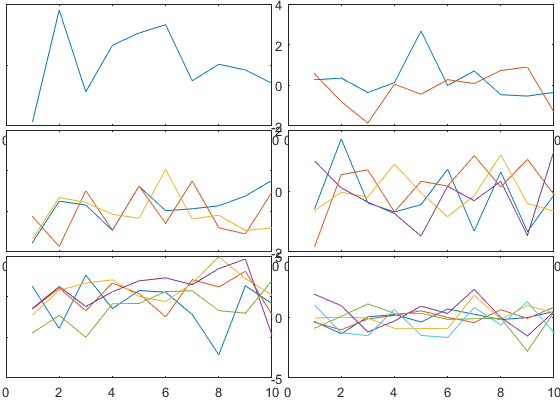

for ii = 1:6;
    axes(ha(ii));
    plot(randn(10,ii));
end

%set(ha(1:4),'XTickLabel',''); set(ha,'YTickLabel','')


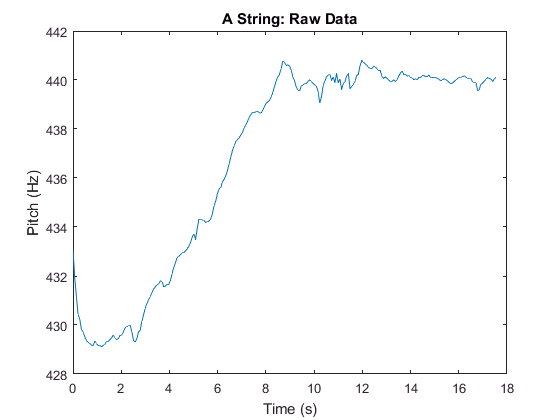

figure
%[ha, pos] = tight_subplot(1,2,[.01 .06],[.3 .3],[.08 .05])
%axes(ha(1));
plot(A_unsmoothed(:,1),A_unsmoothed(:,2));
title('A String: Raw Data')
xlabel('Time (s)')
ylabel('Pitch (Hz)')

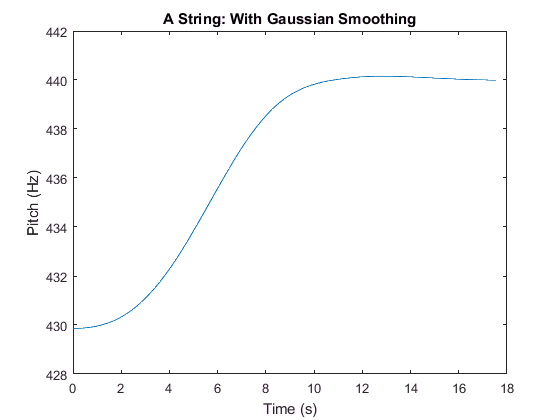

%axes(ha(2));
figure
plot(A_flat(:,1),A_flat(:,2));
title('A String: With Gaussian Smoothing')
xlabel('Time (s)')
ylabel('Pitch (Hz)')

figure
[ha, pos] = tight_subplot(1,2,[.01 .06],[.3 .3],[.08 .05])

ha =   2×1 Axes array:

  Axes
  Axes


pos = 2×1 cell array
    [1×4 double]
    [1×4 double]


%subplot(4,2,1)
axes(ha(1));
A_step_response = stepinfo(A_flat(:,2),A_flat(:,1),440.0,'SettlingTimeThreshold',0.05)

A_step_response = struct with fields:
        RiseTime: 5.6913
    SettlingTime: 9.1875
     SettlingMin: 439.0166
     SettlingMax: 440.1538
       Overshoot: 0.0350
      Undershoot: 0
            Peak: 440.1538
        PeakTime: 12.8120


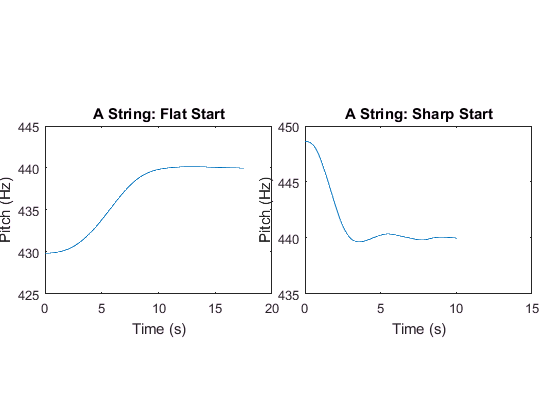

A_step_response.Name = 'A String';
plot(A_flat(:,1),A_flat(:,2));
title('A String: Flat Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')

% subplot(4,2,2)
axes(ha(2));
plot(A_sharp(:,1),A_sharp(:,2));
title('A String: Sharp Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')


% subplot(4,2,3)
figure
[ha, pos] = tight_subplot(1,2,[.01 .06],[.3 .3],[.08 .05])

ha =   2×1 Axes array:

  Axes
  Axes


pos = 2×1 cell array
    [1×4 double]
    [1×4 double]


axes(ha(1));
D_step_response = stepinfo(D_flat(:,2),D_flat(:,1),293.7,'SettlingTimeThreshold',0.05)

D_step_response = struct with fields:
        RiseTime: 3.8155
    SettlingTime: 5.3144
     SettlingMin: 292.7126
     SettlingMax: 293.8553
       Overshoot: 0.0529
      Undershoot: 0
            Peak: 293.8553
        PeakTime: 6.8240


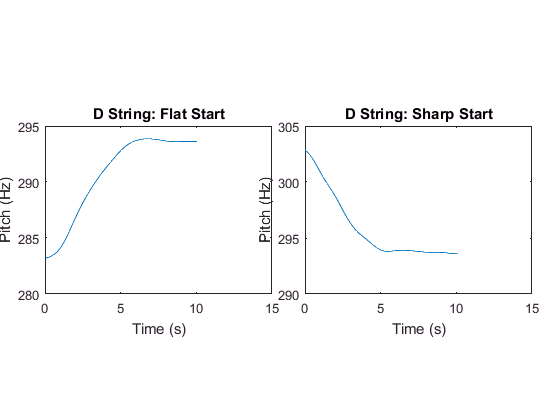

D_step_response.Name = 'D String';
plot(D_flat(:,1),D_flat(:,2));
title('D String: Flat Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')

% subplot(4,2,4)
axes(ha(2));
plot(D_sharp(:,1),D_sharp(:,2));
title('D String: Sharp Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')


figure
[ha, pos] = tight_subplot(1,2,[.01 .06],[.3 .3],[.08 .05])

ha =   2×1 Axes array:

  Axes
  Axes


pos = 2×1 cell array
    [1×4 double]
    [1×4 double]


axes(ha(1));
E_step_response = stepinfo(E_flat(:,2),E_flat(:,1),659.3,'SettlingTimeThreshold',0.1)

E_step_response = struct with fields:
        RiseTime: 2.4183
    SettlingTime: 2.8062
     SettlingMin: 657.3994
     SettlingMax: 659.4291
       Overshoot: 0.0196
      Undershoot: 0
            Peak: 659.4291
        PeakTime: 5.7790


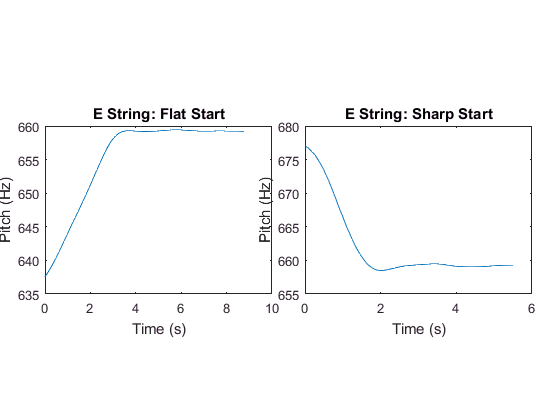

E_step_response.Name = 'E String';
plot(E_flat(:,1),E_flat(:,2));
title('E String: Flat Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')

axes(ha(2));
plot(E_sharp(:,1),E_sharp(:,2));
title('E String: Sharp Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')


figure
[ha, pos] = tight_subplot(1,2,[.01 .06],[.3 .3],[.08 .05])

ha =   2×1 Axes array:

  Axes
  Axes


pos = 2×1 cell array
    [1×4 double]
    [1×4 double]


axes(ha(1));
G_step_response = stepinfo(G_flat(:,2),G_flat(:,1),196.0,'SettlingTimeThreshold',0.05)

G_step_response = struct with fields:
        RiseTime: 4.4697
    SettlingTime: 6.2996
     SettlingMin: 195.2034
     SettlingMax: 195.9682
       Overshoot: 0
      Undershoot: 0
            Peak: 195.9682
        PeakTime: 10.0960


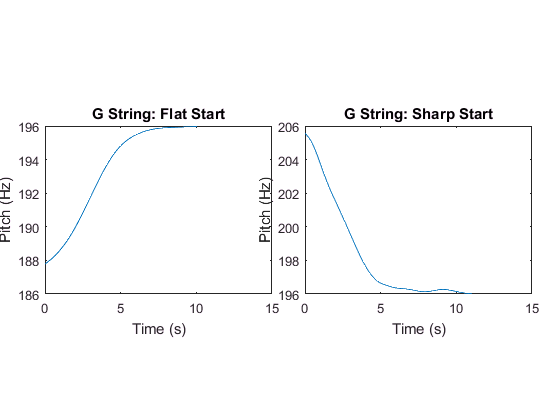

G_step_response.Name = 'G String';
plot(G_flat(:,1),G_flat(:,2));
title('G String: Flat Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')

axes(ha(2));
plot(G_sharp(:,1),G_sharp(:,2));
title('G String: Sharp Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')

## Tables

struct_all = [A_step_response, D_step_response, E_step_response, G_step_response]

struct_all = 1×4 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime
    Name


T = struct2table(struct_all);
T.Properties.RowNames = T.Name;
T.Name = [];
T.Undershoot = [];
T

T = 4×7 table
                RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot     Peak     PeakTime
                ________    ____________    ___________    ___________    _________    ______    ________

    A String    5.6913      9.1875          439.02         440.15         0.034954     440.15    12.812  
    D String    3.8155      5.3144          292.71         293.86          0.05289     293.86     6.824  
    E String    2.4183      2.8062           657.4         659.43         0.019584     659.43     5.779  
    G String    4.4697      6.2996           195.2         195.97                0     195.97    10.096  


bnd = 1;

figure
%subplot(4,2,1)
A_step_response = stepinfo(A_flat(:,2),A_flat(:,1),440.0,'SettlingTimeThreshold',0.05)

A_step_response = struct with fields:
        RiseTime: 5.6913
    SettlingTime: 9.1875
     SettlingMin: 439.0166
     SettlingMax: 440.1538
       Overshoot: 0.0350
      Undershoot: 0
            Peak: 440.1538
        PeakTime: 12.8120


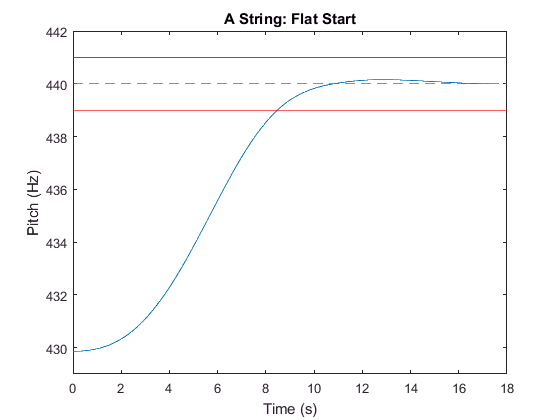

A_step_response.Name = 'A String';
plot(A_flat(:,1),A_flat(:,2));
hold on
ref = 440;
hline = refline(0,ref);
hline.Color = 'm';
hline.LineStyle = '--';
hline.LineWidth = 0.75;
top = refline(0,ref+bnd);
top.Color = 'r';
top.LineWidth = 0.75;
bottom = refline(0,ref-bnd);
bottom.Color = 'r';
bottom.LineWidth = 0.75;
ylim([429 442])
title('A String: Flat Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
print('figures/A_string_flat_start','-dpng')

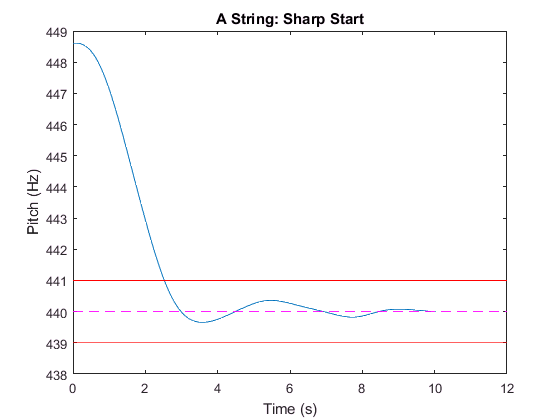


% subplot(4,2,2)
figure
plot(A_sharp(:,1),A_sharp(:,2));
hold on
ref = 440;
hline = refline(0,ref);
hline.Color = 'm';
hline.LineStyle = '--';
hline.LineWidth = 0.75;
top = refline(0,ref+bnd);
top.Color = 'r';
top.LineWidth = 0.75;
bottom = refline(0,ref-bnd);
bottom.Color = 'r';
bottom.LineWidth = 0.75;
ylim([438 449])
title('A String: Sharp Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
print('figures/A_string_sharp_start','-dpng')


% subplot(4,2,3)
figure
D_step_response = stepinfo(D_flat(:,2),D_flat(:,1),293.7,'SettlingTimeThreshold',0.05)

D_step_response = struct with fields:
        RiseTime: 3.8155
    SettlingTime: 5.3144
     SettlingMin: 292.7126
     SettlingMax: 293.8553
       Overshoot: 0.0529
      Undershoot: 0
            Peak: 293.8553
        PeakTime: 6.8240


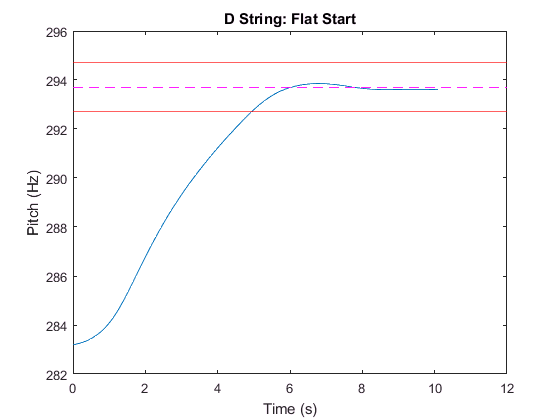

D_step_response.Name = 'D String';
plot(D_flat(:,1),D_flat(:,2));
hold on
ref = 293.7;
hline = refline(0,ref);
hline.Color = 'm';
hline.LineStyle = '--';
hline.LineWidth = 0.75;
top = refline(0,ref+bnd);
top.Color = 'r';
top.LineWidth = 0.75;
bottom = refline(0,ref-bnd);
bottom.Color = 'r';
bottom.LineWidth = 0.75;
ylim([282 296])
title('D String: Flat Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
print('figures/D_string_flat_start','-dpng')

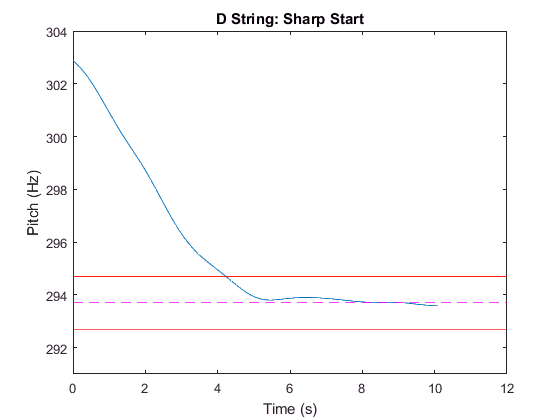


% subplot(4,2,4)
figure
plot(D_sharp(:,1),D_sharp(:,2));
hold on
ref = 293.7;
hline = refline(0,ref);
hline.Color = 'm';
hline.LineStyle = '--';
hline.LineWidth = 0.75;
top = refline(0,ref+bnd);
top.Color = 'r';
top.LineWidth = 0.75;
bottom = refline(0,ref-bnd);
bottom.Color = 'r';
bottom.LineWidth = 0.75;
ylim([291 304])
title('D String: Sharp Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
print('figures/D_string_sharp_start','-dpng')


figure
E_step_response = stepinfo(E_flat(:,2),E_flat(:,1),659.3,'SettlingTimeThreshold',0.1)

E_step_response = struct with fields:
        RiseTime: 2.4183
    SettlingTime: 2.8062
     SettlingMin: 657.3994
     SettlingMax: 659.4291
       Overshoot: 0.0196
      Undershoot: 0
            Peak: 659.4291
        PeakTime: 5.7790


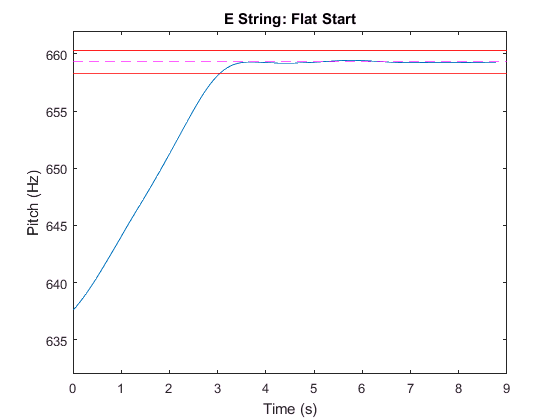

E_step_response.Name = 'E String';
plot(E_flat(:,1),E_flat(:,2));
hold on
ref = 659.3;
hline = refline(0,ref);
hline.Color = 'm';
hline.LineStyle = '--';
hline.LineWidth = 0.75;
top = refline(0,ref+bnd);
top.Color = 'r';
top.LineWidth = 0.75;
bottom = refline(0,ref-bnd);
bottom.Color = 'r';
bottom.LineWidth = 0.75;
ylim([632 662])
title('E String: Flat Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
print('figures/E_string_flat_start','-dpng')

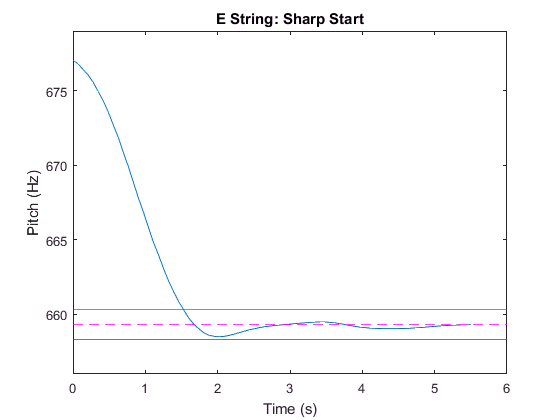


figure
plot(E_sharp(:,1),E_sharp(:,2));
hold on
ref = 659.3;
hline = refline(0,ref);
hline.Color = 'm';
hline.LineStyle = '--';
hline.LineWidth = 0.75;
top = refline(0,ref+bnd);
top.Color = 'r';
top.LineWidth = 0.75;
bottom = refline(0,ref-bnd);
bottom.Color = 'r';
bottom.LineWidth = 0.75;
ylim([656 679])
title('E String: Sharp Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
print('figures/E_string_sharp_start','-dpng')


figure
G_step_response = stepinfo(G_flat(:,2),G_flat(:,1),196.0,'SettlingTimeThreshold',0.05)

G_step_response = struct with fields:
        RiseTime: 4.4697
    SettlingTime: 6.2996
     SettlingMin: 195.2034
     SettlingMax: 195.9682
       Overshoot: 0
      Undershoot: 0
            Peak: 195.9682
        PeakTime: 10.0960


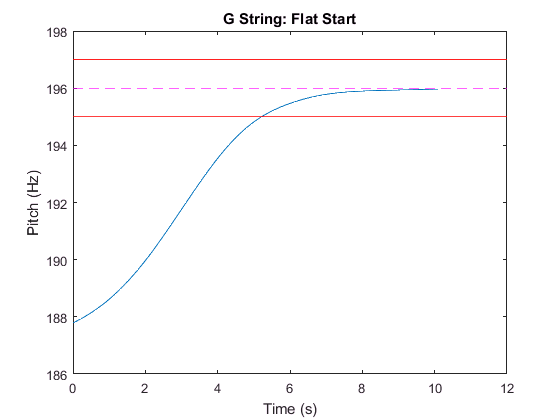

G_step_response.Name = 'G String';
plot(G_flat(:,1),G_flat(:,2));
hold on
ref = 196.0;
hline = refline(0,ref);
hline.Color = 'm';
hline.LineStyle = '--';
hline.LineWidth = 0.75;
top = refline(0,ref+bnd);
top.Color = 'r';
top.LineWidth = 0.75;
bottom = refline(0,ref-bnd);
bottom.Color = 'r';
bottom.LineWidth = 0.75;
ylim([186 198])
title('G String: Flat Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
print('figures/G_string_flat_start','-dpng')

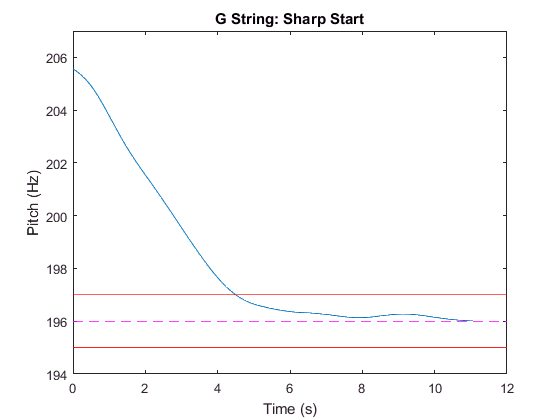


figure
plot(G_sharp(:,1),G_sharp(:,2));
hold on
ref = 196.0;
hline = refline(0,ref);
hline.Color = 'm';
hline.LineStyle = '--';
hline.LineWidth = 0.75;
top = refline(0,ref+bnd);
top.Color = 'r';
top.LineWidth = 0.75;
bottom = refline(0,ref-bnd);
bottom.Color = 'r';
bottom.LineWidth = 0.75;
ylim([194 207])
title('G String: Sharp Start')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
print('figures/G_string_sharp_start','-dpng')